% Set config
addpath('../');
c= Config.Testing(); % change Config depending on the setup.

% Create a camera object to take a picture  of displayed result.
take_pic= false;
if take_pic
    cam= Cam(1,'timeout',Inf);
end

% Load and display a target to display.
target="C:\Users\Admin\Documents\CGH\slm.png"; % path to target image
try 
    im= imread(target);
    im = rgb2gray(im);
catch
    warning("Failed to load target image.")
    im= otslm.simple.aperture(c.res, 20, 'shape', 'square'); 
    % Defaults to square if no image given.
end

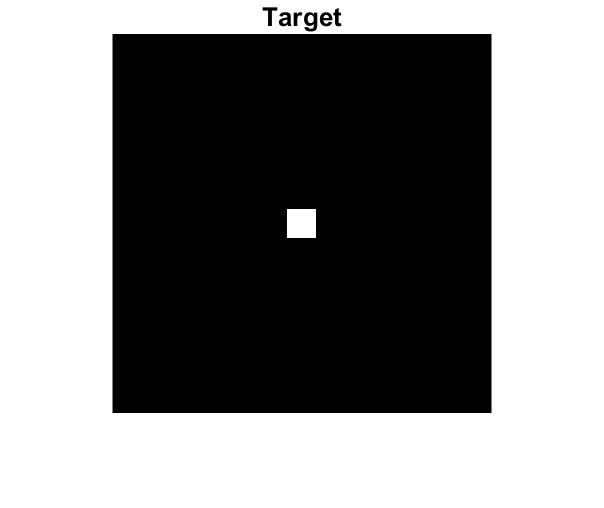


% Display target
figure(1);
imshow(im);
title("Target")

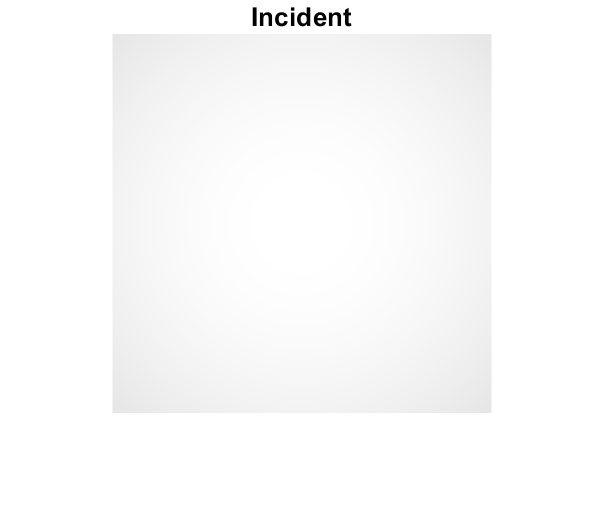

% Set incident illumination
beam= 1;
waist= 780;

% Incident illumination must be given as a function of SLM screen size.
if beam
    incident= @(res) otslm.simple.gaussian(res, waist);
else 
    incident= @(res) ones(res);
end

% Display incident illumination
figure(2);
imshow(incident(c.res));
title("Incident")

% Initialize SLM object
slm= SLM(c, 'f', Inf);
  % executes preceding lines

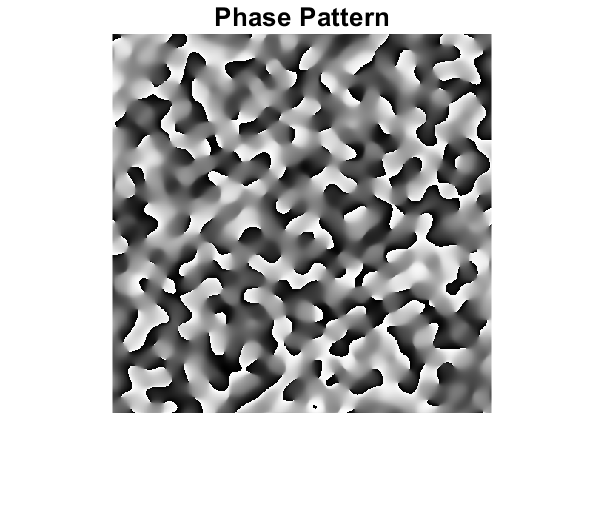

% Set parameters & calculate the phasemask.
alpha= 0.5;
N= 10;
use_gpu= false;

pattern= slm.compute_phasemask(im, 'alpha', alpha, 'use_gpu', use_gpu, 'N', N);

% Create imagesc of incident
figure(3);
imshow(mod(pattern,1));
title("Phase Pattern")

% Configure camera object if being used.
if take_pic
    exposure= 0; % in ms
    gain= 0;
    cam.configure('exposure', log(exposure*10^(-3))/log(2), 'gain', gain);
end

% Set focal length of virtual lens
focal_length= 431; %in mm
slm.f= focal_length;

% Apply a grating to shift pattern in xy-plane

% X Grating period (in pixels)
x= -0.5;

% Y Grating period (in pixels)
y= -2.4;

slm.apply_grating([x,y],false)

% Display image
disp('Displayed to SLM:')

Displayed to SLM:


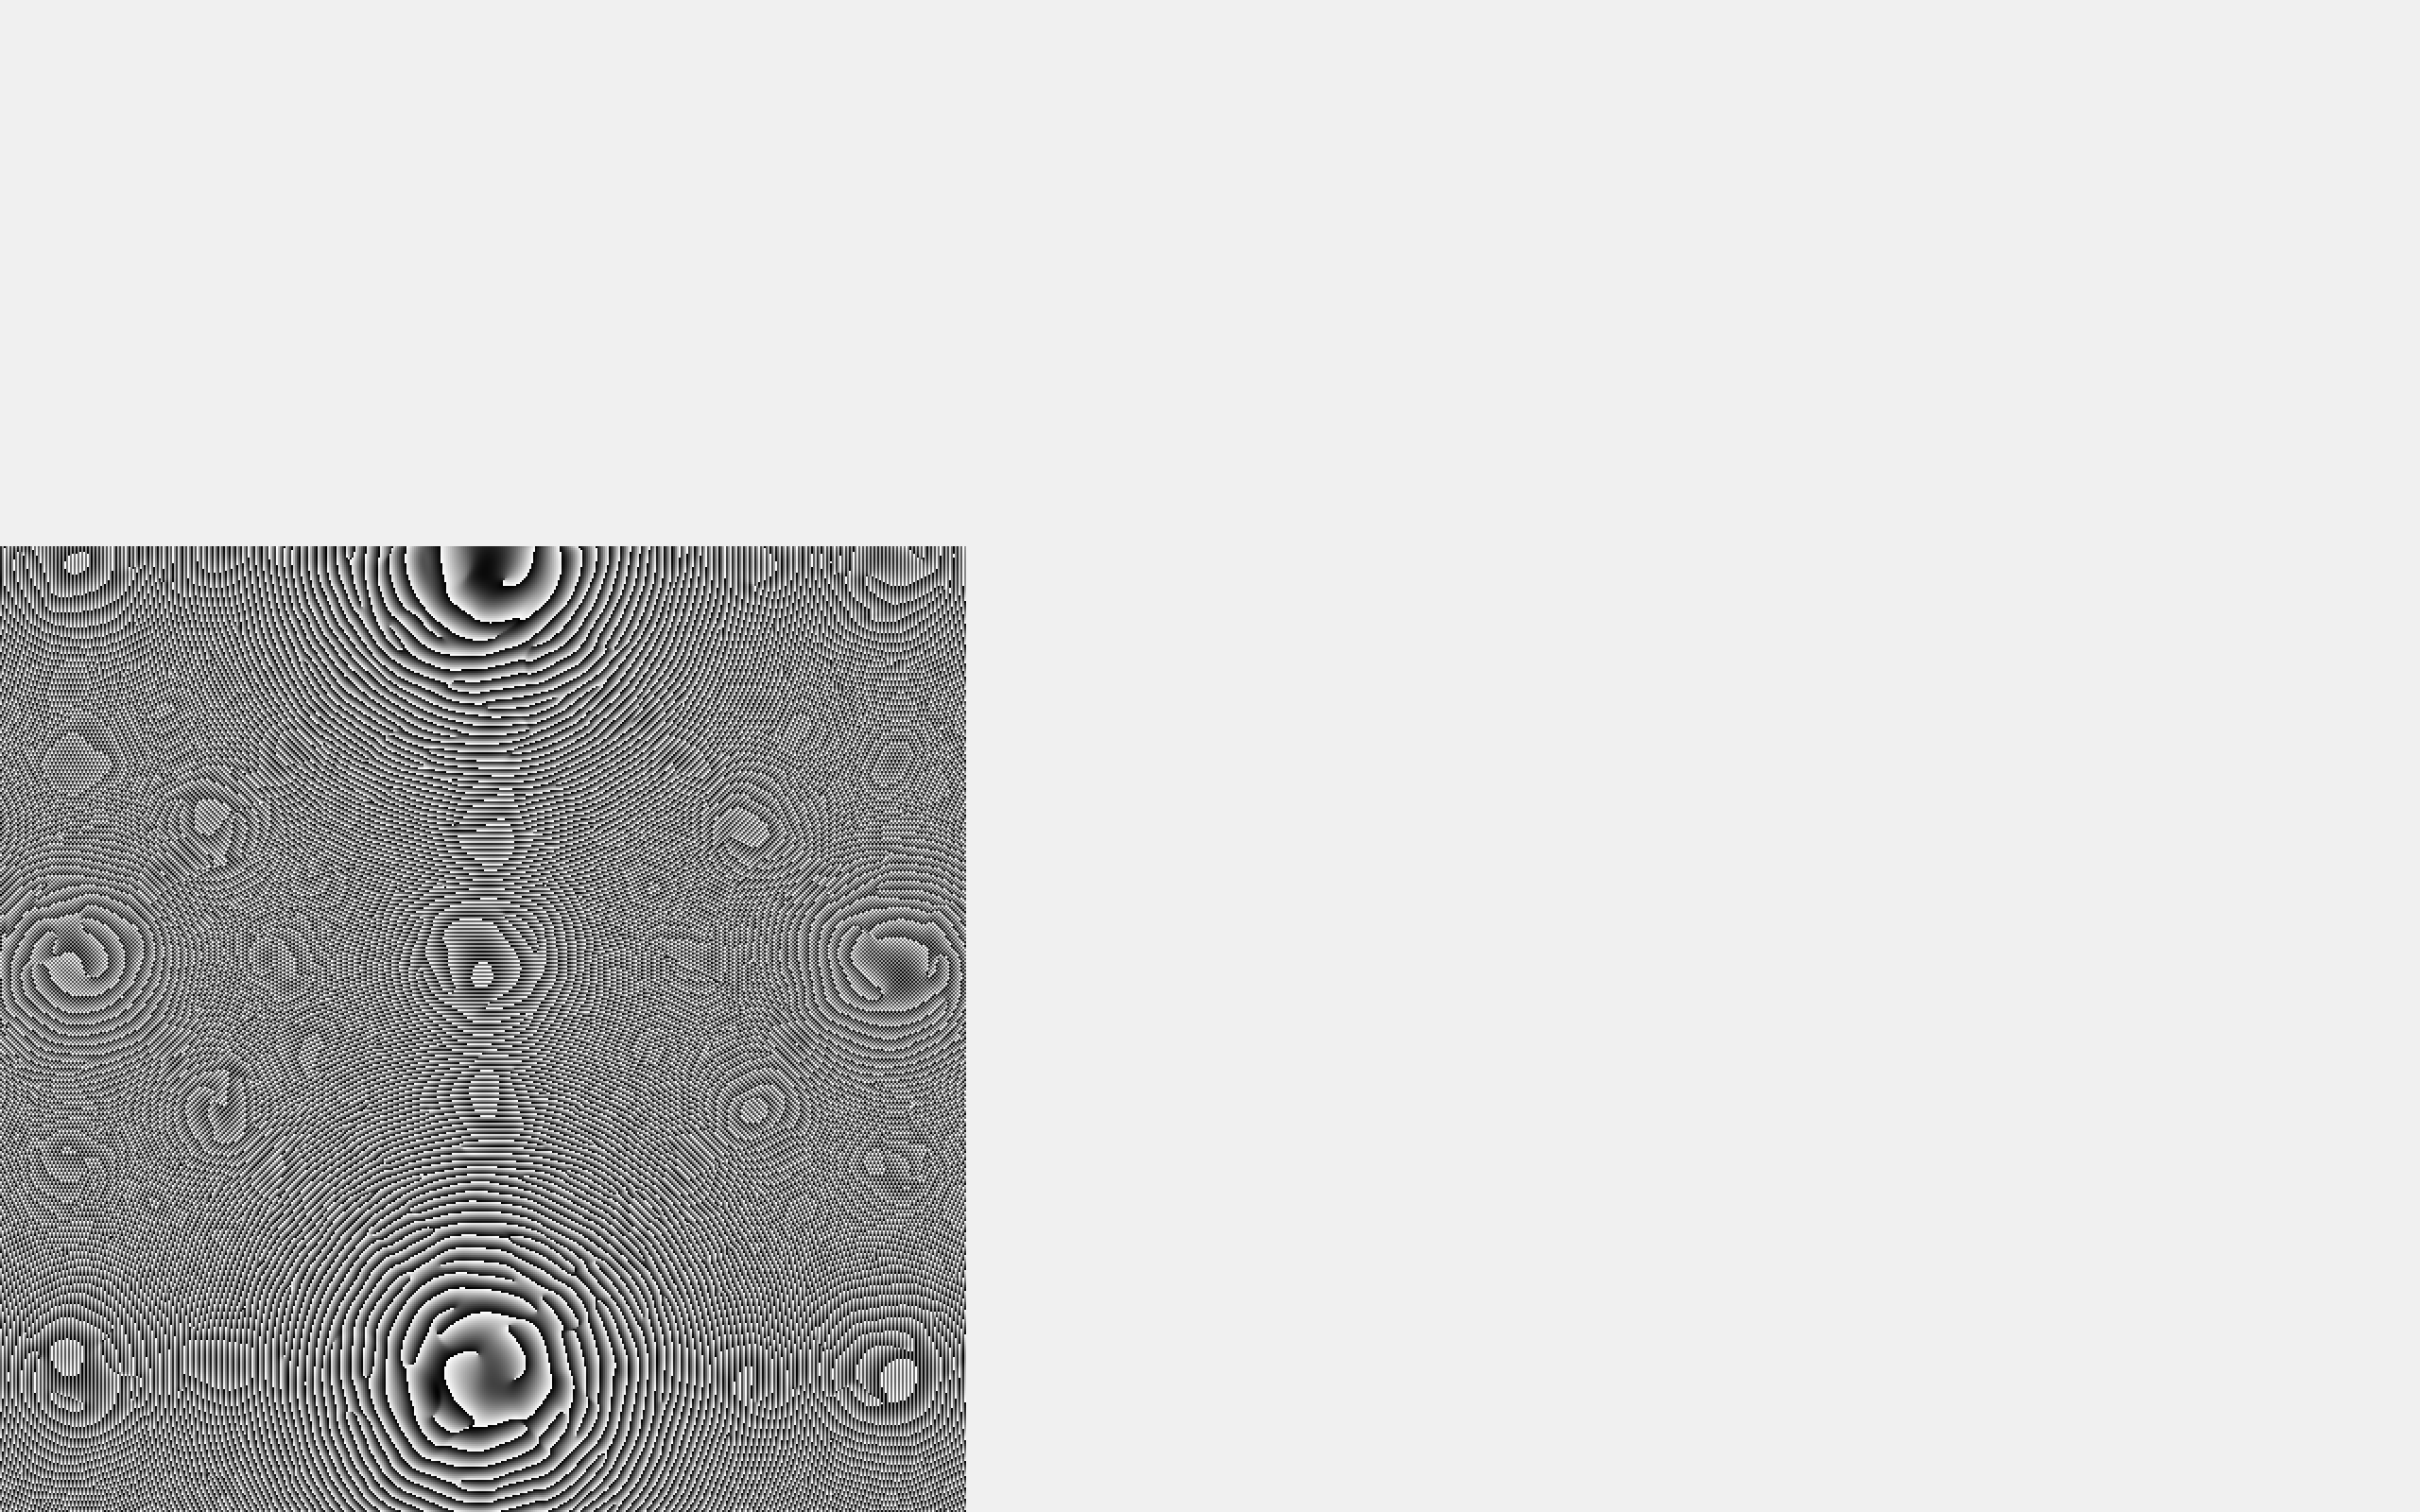

slm.show(pattern);


% Take picture
if take_pic
    pic= cam.capture();
    figure(4);
    imshow(pic);
    title("Result")
end
 

slm.reset();
 